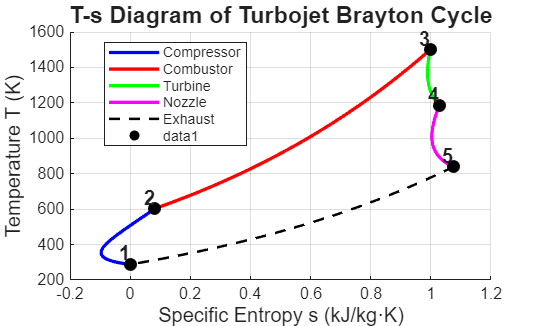

% --- Air Constants ---
gamma = 1.4;
Cp = 1.005; 
R = 0.287;

% --- General constants ---
rp = 10;
P1 = 100;
T1 = 288;
T3 = 1500;
eff_c = 0.85;
eff_t = 0.90;
s1 = 0;

% --- State Calculations ---
P2 = P1 * rp;
T2s = T1 * rp^((gamma-1)/gamma);
T2 = T1 + ((T2s-T1)/eff_c);
s2 = Cp*log(T2/T1) - R*log(P2/P1);

P3 = P2;
s3 = Cp*log(T3/T1) - R*log(P3/P1);

T4 = T3 - (T2 - T1);
T4s = T3 - (T3 - T4)/eff_t;
P4  = P3 * (T4s/T3)^(gamma/(gamma-1));
s4 = Cp*log(T4/T1) - R*log(P4/P1);

P5 = P1;
T5s = T4 * (P5/P4)^((gamma-1)/gamma);
T5 = T4 - (T4-T5s) * eff_t;
s5 = Cp*log(T5/T1) - R*log(P5/P1);

% --- Path Generation ---
T_12 = linspace(T1, T2, 100);
P_12 = linspace(P1, P2, 100);
S_12 = Cp*log(T_12/T1) - R*log(P_12/P1);

T_23 = linspace(T2, T3, 100);
P_23 = P2;
S_23 = Cp*log(T_23/T1) - R*log(P_23/P1);

T_34 = linspace(T3, T4, 100);
P_34 = linspace(P3, P4, 100);
S_34 = Cp*log(T_34/T1) - R*log(P_34/P1);

T_45 = linspace(T4, T5, 100);
P_45 = linspace(P4, P5, 100);
S_45 = Cp*log(T_45/T1) - R*log(P_45/P1);

T_51 = linspace(T5, T1, 100);
P_51 = P1;
S_51 = Cp*log(T_51/T1) - R*log(P_51/P1);

% --- Visualization ---
figure(1); clf;
set(gcf, 'Color', 'w'); % White background
hold on; grid on;

% Plotting lines with specific colors
plot(S_12, T_12, 'b', 'LineWidth', 2, 'DisplayName', 'Compressor');
plot(S_23, T_23, 'r', 'LineWidth', 2, 'DisplayName', 'Combustor');
plot(S_34, T_34, 'g', 'LineWidth', 2, 'DisplayName', 'Turbine');
plot(S_45, T_45, 'm', 'LineWidth', 2, 'DisplayName', 'Nozzle');
plot(S_51, T_51, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Exhaust');

% Adding State Points
s_points = [s1, s2, s3, s4, s5];
t_points = [T1, T2, T3, T4, T5];
scatter(s_points, t_points, 60, 'k', 'filled');

% Adding Text Labels
labels = {' 1', ' 2', ' 3', ' 4', ' 5'};
text(s_points, t_points, labels, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 12, 'FontWeight', 'bold');

% Formatting
xlabel('Specific Entropy s (kJ/kg·K)', 'FontSize', 12);
ylabel('Temperature T (K)', 'FontSize', 12);
title('T-s Diagram of Turbojet Brayton Cycle', 'FontSize', 14);
legend('Location', 'best');



V_Exhaust = sqrt(2*Cp*1000*(T4-T5));
Qin = Cp*(T3-T2);
Wnet = 0.5*(V_Exhaust^2);
eff_thermal = Wnet/Qin;
fprintf('\n--- Turbojet Performance ---\n');


--- Turbojet Performance ---


fprintf('Exhaust Velocity: %.2f m/s\n', V_Exhaust);

Exhaust Velocity: 833.52 m/s


fprintf('Thermal Efficiency: %.2f%%\n', eff_thermal);

Thermal Efficiency: 385.49%


fprintf('Specific Thrust: %.2f N·s/kg\n', V_Exhaust); % For stationary engine

Specific Thrust: 833.52 N·s/kg
